clear all
sympref('FloatingPointOutput', false)

ans = logical
   0


## Problem 2

### Part A

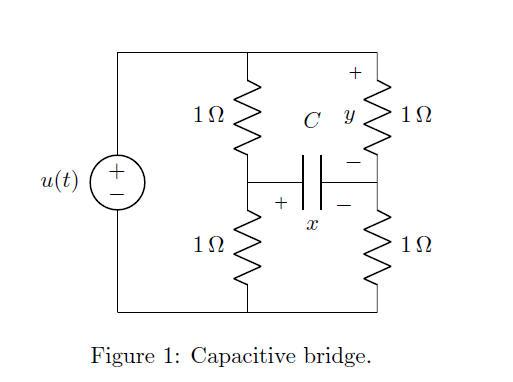

syms i_1 i_2 i_3 u x x_dot y C
%Loop 1 equation
l1eqn = i_1 + i_2 == u

$$l1eqn = i_{1}+i_{2}=u$$


%Node 1 equation
n1eqn = i_1 - i_2 == C*x_dot

$$n1eqn = i_{1}-i_{2}=C\,\dot{x}$$


%Loop 2 equation
l2eqn = -i_1 + y - x == 0

$$l2eqn = -x+y-i_{1}=0$$


%Node 2 equation
n2eqn = -y + i_3 == C*x_dot

$$n2eqn = -y+i_{3}=C\,\dot{x}$$


%Loop 2 equation
l3eqn = -i_2 + x + i_3 == 0

$$l3eqn = x-i_{2}+i_{3}=0$$


eqns = [l1eqn;n1eqn;l2eqn;n2eqn;l3eqn]

$$eqns = \left[\begin{array}{c} i_{1}+i_{2}=u\\ i_{1}-i_{2}=C\,\dot{x}\\ -x+y-i_{1}=0\\ -y+i_{3}=C\,\dot{x}\\ x-i_{2}+i_{3}=0 \end{array}\right]$$

state_eqn = 0 == eliminate(eqns, [i_1 i_2 i_3 y]);
state_eqn = isolate(state_eqn, x_dot)

$$state\_eqn = \dot{x}=-\frac{x}{C}$$

output_eqn = 0 == eliminate(eqns, [i_1 i_2 i_3 x_dot])

$$output\_eqn = 0=x-2\,y+u$$

output_eqn = isolate(output_eqn, y)

$$output\_eqn = y=\frac{x}{2}+\frac{u}{2}$$

### Part B

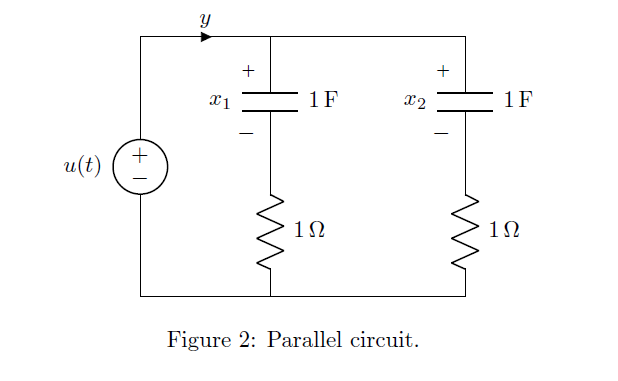

syms x_1 x_2 x_dot_1 x_dot_2 

%Loop 1 equation
l1eqn = x_1 + i_1 - u == 0

$$l1eqn = x_{1}-u+i_{1}=0$$


%Loop 2 equation
l2eqn = x_2 + i_2 - u == 0

$$l2eqn = x_{2}-u+i_{2}=0$$


%Node 1 equation
n1eqn = y == x_dot_1 + x_dot_2

$$n1eqn = y={\dot{x}}_{1}+{\dot{x}}_{2}$$


%Node 2 equation
n2eqn = i_1 == x_dot_1

$$n2eqn = i_{1}={\dot{x}}_{1}$$


%Node 3 equation
n3eqn = i_2 == x_dot_2

$$n3eqn = i_{2}={\dot{x}}_{2}$$


eqns = [l1eqn;l2eqn;n1eqn;n2eqn;n3eqn]

$$eqns = \left[\begin{array}{c} x_{1}-u+i_{1}=0\\ x_{2}-u+i_{2}=0\\ y={\dot{x}}_{1}+{\dot{x}}_{2}\\ i_{1}={\dot{x}}_{1}\\ i_{2}={\dot{x}}_{2} \end{array}\right]$$

solved_state_eqns = eliminate(eqns, [i_1 i_2 y])

$$solved\_state\_eqns = \left[-x_{2}-{\dot{x}}_{2}+u,x_{1}-x_{2}+{\dot{x}}_{1}-{\dot{x}}_{2}\right]$$

solved_state_eqns = [0;0] == [solved_state_eqns(1);solved_state_eqns(2)];
solved_state_eqns = [solved_state_eqns(1)-solved_state_eqns(2);solved_state_eqns(1)];
solved_state_eqns = [isolate(solved_state_eqns(1), x_dot_1);isolate(solved_state_eqns(2), x_dot_2)]

$$solved\_state\_eqns = \left[\begin{array}{c} {\dot{x}}_{1}=-x_{1}+u\\ {\dot{x}}_{2}=-x_{2}+u \end{array}\right]$$

solved_output_eqn = 0 == eliminate(eqns, [i_1 i_2 x_dot_1 x_dot_2]);
solved_output_eqn = isolate(solved_output_eqn, y)

$$solved\_output\_eqn = y=-x_{1}-x_{2}+2\,u$$

## Problem 3 

### Part A

State space model of spring mass system:

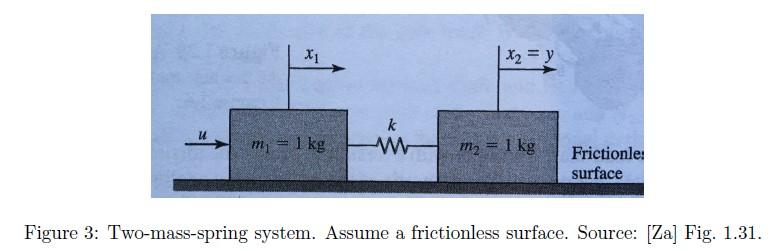

m1 = 1;
m2 = 1;
k = 1;

A = [0      0   1  0
        0      0   0  1
      -k/m1  k/m1  0  0
       k/m2 -k/m2  0  0];

B = [ 0
      0 
     1/m1
      0 ];

C = [ 0 1 0 0];

D = 0;

sys = ss(A,B,C,D);

eig(A)

ans =   -0.0000 + 1.4142i
  -0.0000 - 1.4142i
  -0.0000 + 0.0000i
   0.0000 + 0.0000i


### Controllabilitry Gramian $W$


$$W(t) = \int_{0}^{t} e^{A\tau}BB^Te^{A^T\tau} \,d\tau$$


syms Tau t n

c_integrand = exp(A*Tau)*(B*B.')*exp(A.'*Tau)

$$c\_integrand = \left[\begin{array}{cccc} {\mathrm{e}}^{2\,Τ} & {\mathrm{e}}^{Τ} & {\mathrm{e}}^{Τ} & {\mathrm{e}}^{Τ}\\ {\mathrm{e}}^{Τ} & 1 & 1 & 1\\ {\mathrm{e}}^{Τ} & 1 & 1 & 1\\ {\mathrm{e}}^{Τ} & 1 & 1 & 1 \end{array}\right]$$

W(t) = int(c_integrand,Tau, 0, t)

$$W(t) = \left[\begin{array}{cccc} \frac{{\mathrm{e}}^{2\,t}}{2}-\frac{1}{2} & {\mathrm{e}}^{t}-1 & {\mathrm{e}}^{t}-1 & {\mathrm{e}}^{t}-1\\ {\mathrm{e}}^{t}-1 & t & t & t\\ {\mathrm{e}}^{t}-1 & t & t & t\\ {\mathrm{e}}^{t}-1 & t & t & t \end{array}\right]$$

det_W = det(W)

$$det\_W(t) = 0$$

### Evaluate $W$ at the time values $t_1 = 10 , ~t_2 = 20, ~ and~t_3 = 100$ seconds and find the eigenvalues and eigenvectors

Also determine wether or not $W(t_1), W(t_2), W(t_3)$ are convergant


t1 = 10;
t2 = 20;
t3 = 100;
W1 = double(W(t1))

W1 = 	1.0e+08 *

    2.4258    0.0002    0.0002    0.0002
    0.0002    0.0000    0.0000    0.0000
    0.0002    0.0000    0.0000    0.0000
    0.0002    0.0000    0.0000    0.0000


W2 = double(W(t2))

W2 = 	1.0e+17 *

    1.1769    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000


W3 = double(W(t3))

W3 = 	1.0e+86 *

    3.6130    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000



%t1 = 10 
% V is the matrix of eigenvectors and D is a diagonal matrix of eigenvalues
[V1, W_bar_1] = eig(W1);
%Make sure they are ordered from largest to smallest
[eigvals1,ind1] = sort(diag(W_bar_1), 'descend')

eigvals1 = 	1.0e+08 *

    2.4258
    0.0000
    0.0000
    0.0000


ind1 =      4
     3
     2
     1


W_bar_s1 = W_bar_1(ind1,ind1)

W_bar_s1 = 	1.0e+08 *

    2.4258         0         0         0
         0    0.0000         0         0
         0         0    0.0000         0
         0         0         0    0.0000


Since the matrix $\bar{W}_1$, which is in the eigenbasis of $W_1$, has an eigenvalue greater than 1, $$\lim_{n \to \infty} {W_1}^n~\neq~ \tilde{0}$ $. I.e. $W_1$ does not converge (see hand calculations for proof).

Vs1 = V1(:,ind1) 

Vs1 =     1.0000   -0.0002   -0.0000    0.0000
    0.0001    0.5774    0.3510   -0.7372
    0.0001    0.5774    0.4629    0.6726
    0.0001    0.5774   -0.8139    0.0646



%t2 = 20
% V is the matrix of eigenvectors and D is a diagonal matrix of eigenvalues
[V2, W_bar_2] = eig(W2);
%Make sure they are ordered from largest to smallest
[eigvals2,ind2] = sort(diag(W_bar_2), 'descend')

eigvals2 = 	1.0e+17 *

    1.1769
    0.0000
   -0.0000
   -0.0000


ind2 =      4
     3
     2
     1


W_bar_s2 = W_bar_2(ind2,ind2)

W_bar_s2 = 	1.0e+17 *

    1.1769         0         0         0
         0    0.0000         0         0
         0         0   -0.0000         0
         0         0         0   -0.0000


Since the matrix $\bar{W}_2$, which is in the eigenbasis of $W_2$, has an eigenvalue greater than 1, $$\lim_{n \to \infty} {W_2}^n~\neq~ \tilde{0}$ $. I.e. $W_2$ does not converge (see hand calculations for proof).

Vs2 = V2(:,ind2)

Vs2 =     1.0000    0.0000   -0.0000    0.0000
    0.0000   -0.6009   -0.7597    0.2487
    0.0000   -0.5504    0.1676   -0.8179
    0.0000   -0.5797    0.6283    0.5189



%t3 = 100
% V is the matrix of eigenvectors and D is a diagonal matrix of eigenvalues
[V3, W_bar_3] = eig(W3);
%Make sure they are ordered from largest to smallest
[eigvals3,ind3] = sort(diag(W_bar_3), 'descend')

eigvals3 = 	1.0e+86 *

    3.6130
    0.0000
   -0.0000
   -0.0000


ind3 =      4
     3
     2
     1


W_bar_s3 = W_bar_3(ind3,ind3)

W_bar_s3 = 	1.0e+86 *

    3.6130         0         0         0
         0    0.0000         0         0
         0         0   -0.0000         0
         0         0         0   -0.0000


Since the matrix $\bar{W}_3$, which is in the eigenbasis of $W_3$, has an eigenvalue greater than 1, $$\lim_{n \to \infty} {W_3}^n~\neq~ \tilde{0}$ $. I.e. $W_3$ does not converge (see hand calculations for proof).

Vs3 = V3(:,ind3)

Vs3 =     1.0000         0         0         0
    0.0000    0.0000    1.0000   -0.0000
         0    1.0000   -0.0000    0.0000
    0.0000    0.0000   -0.0000   -1.0000


### Which States Are Most Controllable?